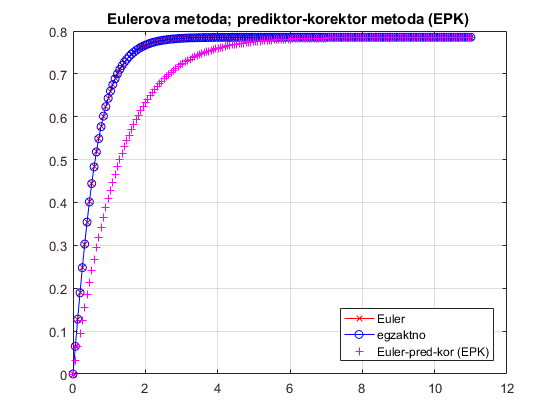

% Numericka analiza 2
% Vjezbe 14.4.2020. 
%
% f    = inline('cos(2*y)','t','y') ; 
% y_ex = inline('0.5*asin((exp(4*t)-1)./(exp(4*t)+1))','t') ;
% .... ili ovako (bolje, iz raznih razloga koji su ovdje nebitni)
%
% Jednostavan primjer ODJ y'(t) = f(t,y(t)) na (a,b]
f    = @(t,y) cos(2*y)                             ; 
y_ex = @(t)   0.5*asin((exp(4*t)-1)./(exp(4*t)+1)) ; % tocno rjesenje

a  = 0  ; b = 11 ; % interval (a,b]
y0 = 0           ; % inicijalni uvjet 
n  = 170          ; % broj tocaka diskretizacije; probaj 30, 50, 100 

[t,YE]   = odjAB5( f, a, b, y0, n )         ; % Eulerova metoda
[t,YEPC] = odjEuler2( f, a, b, y0, n ) ; % Euler + korektor
[t,YRK4] = odjrk4( f, a, b, y0, n )           ; % RK4

% provjera - usporedba s tocnim rjesenjem 

figure(1)
plot( t, YE, 'rx-', t, y_ex(t),'bo-',t, YEPC,'m+' ), grid
legend('Euler','egzaktno','Euler-pred-kor (EPK)','Location','SouthEast')
title('Eulerova metoda; prediktor-korektor metoda (EPK) ')

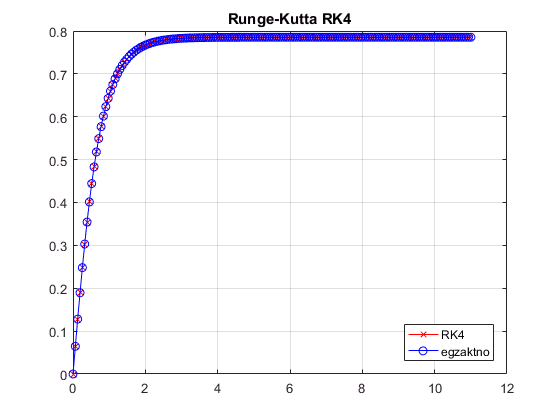


figure(2)
plot( t, YRK4, 'rx-', t, y_ex(t),'bo-' ), grid
legend('RK4','egzaktno','Location','SouthEast')
title('Runge-Kutta RK4')

%
%..........................................................................
%
% Lorenzov sistem
%

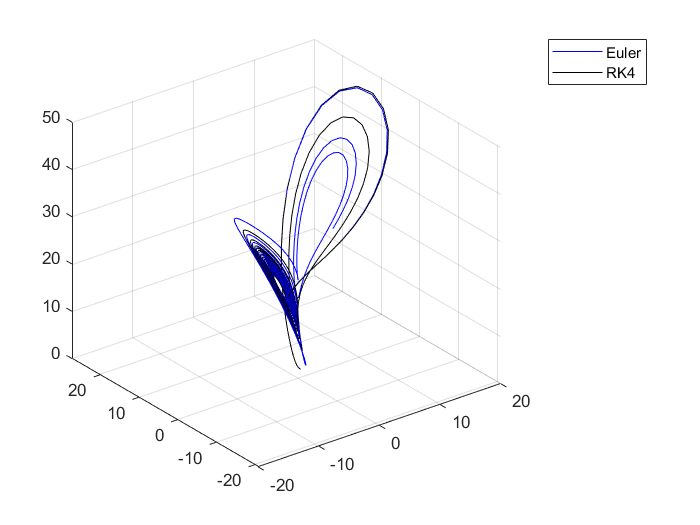

sigma =10; beta = 8/3; rho = 28;
y0 = [ 1 1 1] ;
a = 0 ; b = 15 ; 
n = 1000 ; 

[t,YE]   = euler_sodj( @lorenz63, a, b, y0, n, sigma, beta, rho ) ;
[t,YEPC] = euler_predcor_sodj( @lorenz63, a, b, y0, n, sigma, beta, rho ) ; 
[t,YRK4] = RK4_sodj( @lorenz63, a, b, y0, n, sigma, beta, rho ) ;

figure(3)
plot3(YE(1,:), YE(2,:), YE(3,:), 'b', YRK4(1,:), YRK4(2,:), YRK4(3,:), 'k'), grid
legend('Euler', 'RK4')

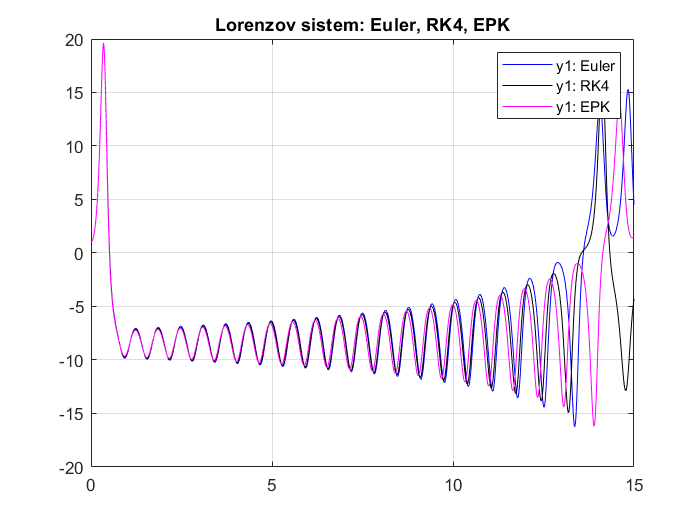


figure(4)
plot( t, YE(1,:), 'b', t, YRK4(1,:), 'k', t, YEPC(1,:), 'm'), grid
legend('y1: Euler', 'y1: RK4', 'y1: EPK'), title('Lorenzov sistem: Euler, RK4, EPK')

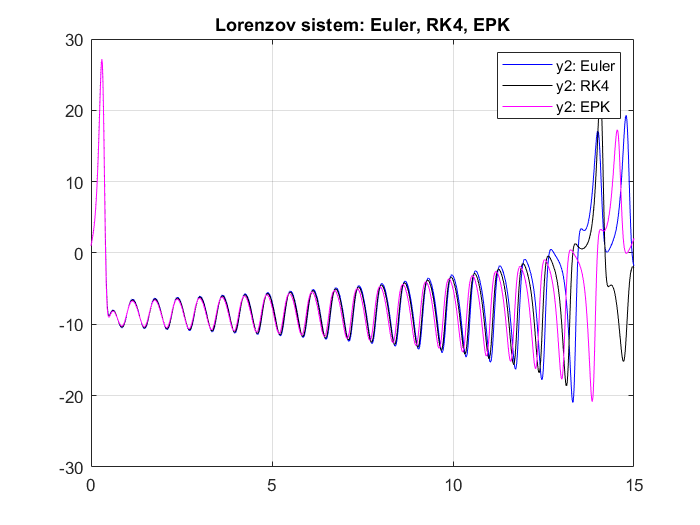

figure(5)
plot( t, YE(2,:), 'b', t, YRK4(2,:), 'k', t, YEPC(2,:), 'm'), grid
legend('y2: Euler', 'y2: RK4', 'y2: EPK'), title('Lorenzov sistem: Euler, RK4, EPK')

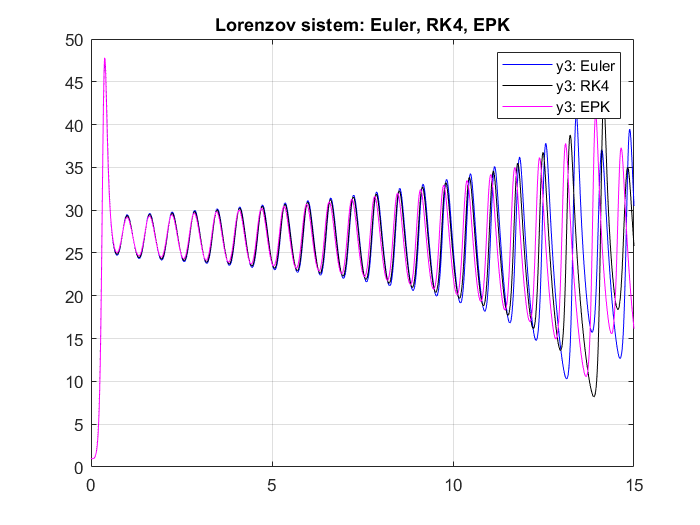

figure(6)
plot( t, YE(3,:), 'b', t, YRK4(3,:), 'k', t, YEPC(3,:), 'm'), grid
legend('y3: Euler', 'y3: RK4', 'y3: EPK'), title('Lorenzov sistem: Euler, RK4, EPK')

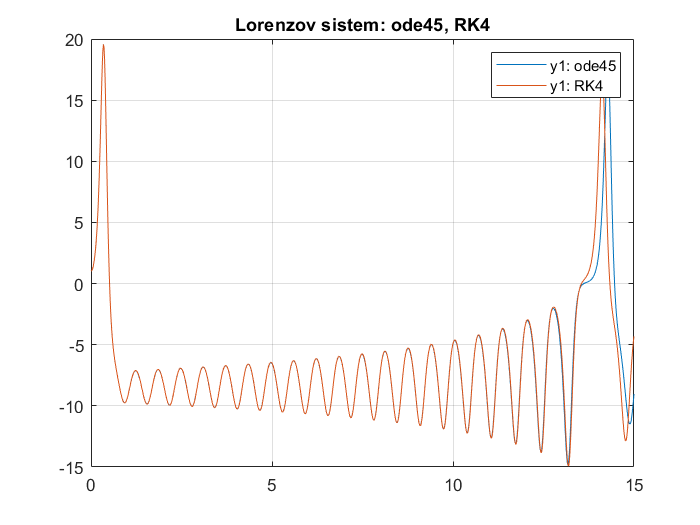


[t,YODE45]=ode45(@lorenz63,t,y0,[],sigma,beta,rho);
figure(7)
plot( t, YODE45(:,1), t, YRK4(1,:)), grid
legend('y1: ode45', 'y1: RK4'), title('Lorenzov sistem: ode45, RK4')

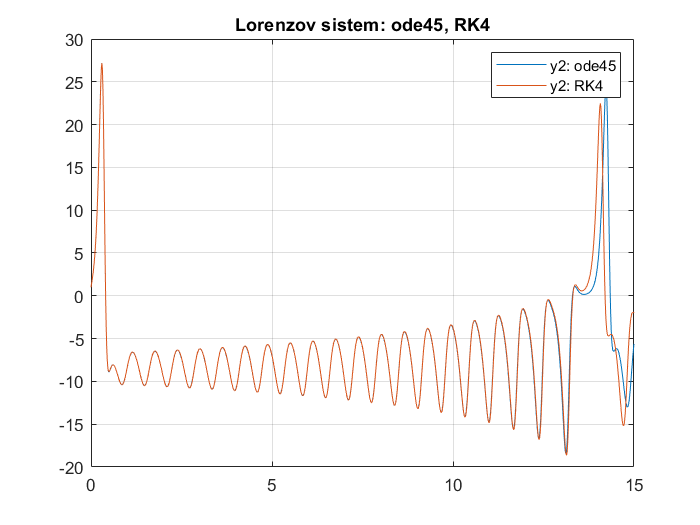

figure(8)
plot( t, YODE45(:,2), t, YRK4(2,:)), grid
legend('y2: ode45', 'y2: RK4'), title('Lorenzov sistem: ode45, RK4')

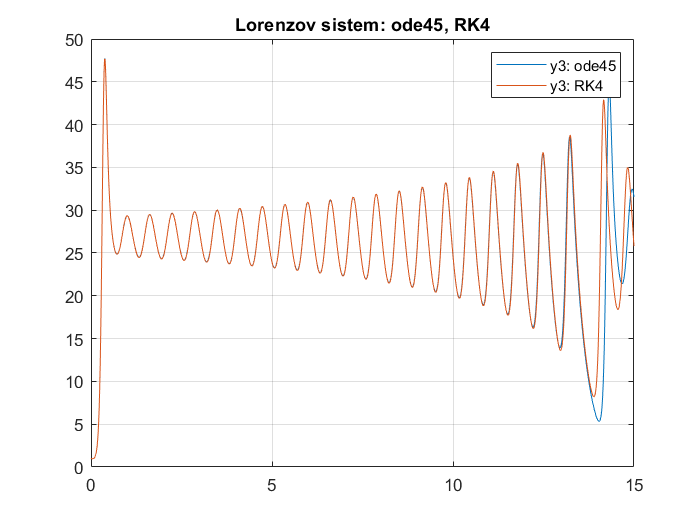

figure(9)
plot( t, YODE45(:,3), t, YRK4(3,:)), grid
legend('y3: ode45', 'y3: RK4'), title('Lorenzov sistem: ode45, RK4')

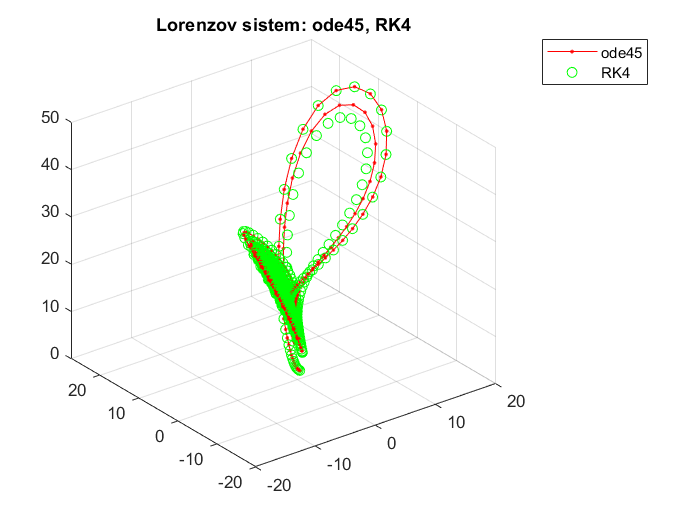


figure(10)
plot3(YODE45(:,1), YODE45(:,2), YODE45(:,3), 'r.-', YRK4(1,:), YRK4(2,:), YRK4(3,:), 'go'), grid
legend('ode45', 'RK4'), title('Lorenzov sistem: ode45, RK4')

%..........................................................................
% Van der Pol-ova jednadzba
% y''(t) - mu*(1-y(t)^2) y'(t) + y(t) = 0 
% zapisana kao sustav dvije ODJ
 mu = 25 ; 
 a  = 0 ;  b = 100 ; % interval (a,b]
 y0 = [ 2 0]       ; % inicijalni uvjet
 n  = 1000 ; 
 [t,YRK4]   = odjABM4( @VanderPol, a, b, y0, n, mu ) ;

Index exceeds matrix dimensions.

Error in VanderPol (line 6)
y(1) = x(2)                     ; 

Error in odjABM4>@(z)-z+y(:,i)+h/720*(251*feval(f,x(i+1),z,varargin{:})+646*f0-264*f1+106*f2-19*f3) (line 11)
    y(:,i+1)=fsolve(@(z) -z + y(:,i)+h/720*(251*feval(f,x(i+1),z,varargin{:})+646*f0-264*f1+106*f2-19*f3),x(i+1),options);

Error in 

 [t,YODE45] = ode45(@VanderPol,t,y0,[],mu)            ; % Matlab, probaj sa ode23s
 
 figure(11)
 plot( t, YODE45(:,1), 'r', t, YODE45(:,2), 'g'), grid
 legend('y1', 'y2','Location','SouthEast'), title('Van der Pol (ode45)')
 figure(12)
 plot(t, YRK4(1,:), 'b', t, YRK4(2,:), 'm' ), grid
 legend('y1', 'y2','Location','SouthEast'), title('Van der Pol  (RK4)')
 

 %.........................................................................
 % Robertsonov sustav ODJ
 a = 0 ; 
 b = 10 ; 
 n = 500 ; 
 y0 = [ 1 0 0 ] ;
 [t,YRK4]   = RK4_sodj( @Robertson, a, b, y0, n ) ;
 [t,YODE45] = ode45(@Robertson,t,y0,[])           ; % Matlab, probaj sa ode23s
 
 figure(13)
 plot(  t, YODE45(:,2), 'g'), grid
 legend('y1', 'Location','SouthEast'), title(' Robertson (ode45)')
 figure(14)
 plot(t, YRK4(1,:), 'b', t, YRK4(2,:), 'm' ), grid
 legend('y1', 'y2','Location','SouthEast'), title('Robertson (RK4)')


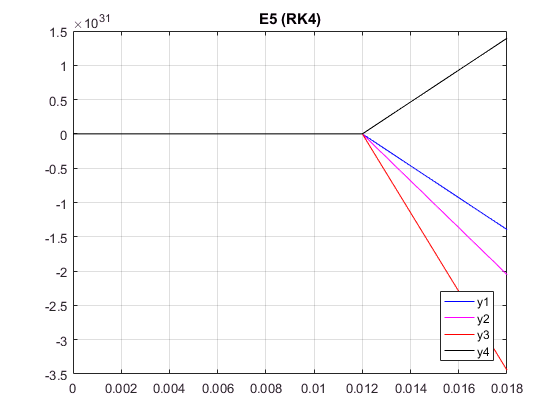

%.........................................................................
 % E5 sustav ODJ
 a = 0 ; 
 b = 15 ; 
 A = 7.89e-10; B = 1.1e7;
 C = 1.13e3; M = 1e6;
 n = 2500 ; 
 y0 = [ 1.76e-3 0 0 0 ] ;
 [t,YRK4]   = odjTrapez( @E5, a, b, y0, n, A, B, C, M ) ;
 [t, YAB4]  = odjAB5(@E5, a, b, y0, n, A, B, C, M);
 [t,YODE45] = ode45(@E5,t,y0,[], A, B, C, M)           ;
 
 
 figure(15)
 plot(t, YRK4(1,:), 'b', t, YRK4(2,:), 'm', t, YRK4(3,:), 'r', t, YRK4(4, :), 'k' ), grid
 legend('y1', 'y2','y3', 'y4', 'Location','SouthEast'), title('E5 (RK4)')

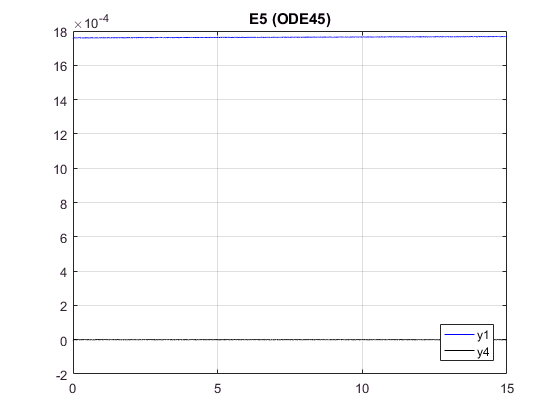

 
 figure(16)
 plot(t, YODE45(:,1), 'b', t, YODE45(:, 4), 'k' ), grid
 legend('y1', 'y4', 'Location','SouthEast'), title('E5 (ODE45)')

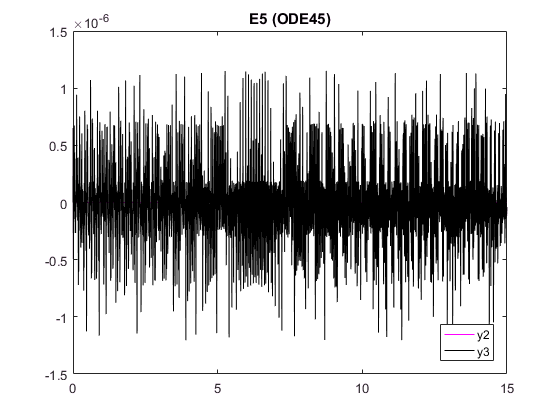

 
 figure(17)
 plot(t, YODE45(:, 2), 'm', t, YODE45(:,3), 'k')
 legend('y2','y3', 'Location','SouthEast'), title('E5 (ODE45)')

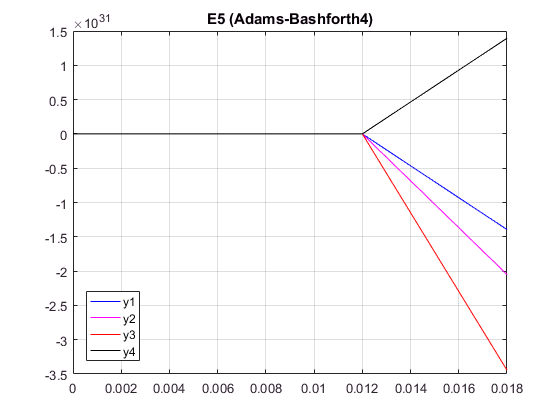

 
 figure(15)
 plot(t, YAB4(1,:), 'b', t, YAB4(2,:), 'm', t, YAB4(3,:), 'r', t, YAB4(4, :), 'k' ), grid
 legend('y1', 'y2','y3', 'y4', 'Location','SouthWest'), title('E5 (Adams-Bashforth4)')